## 利用对数变换将暗像素映射到高灰度

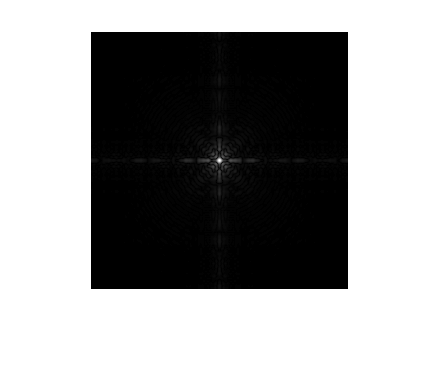

f = imread('./DIP-Ex/pic/dipum_images_ch03/Fig0305(a)(spectrum).tif');
imshow(f);

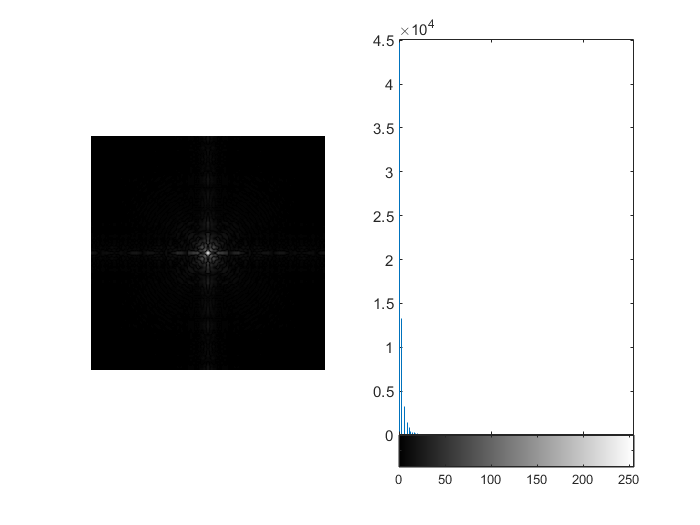

figure
subplot(1, 2, 1), imshow(f);
subplot(1, 2, 2), imhist(f);
axis tight

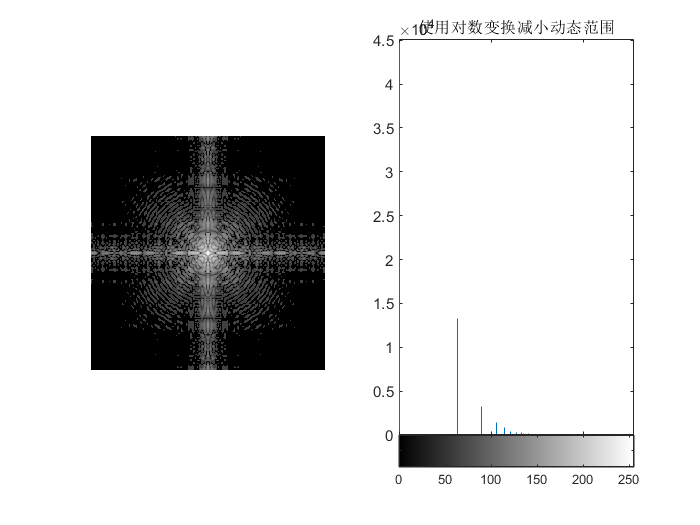

g = im2uint8(mat2gray(1 * log(1 + double(f))));
% g = im2uint8(mat2gray(f));
figure, subplot(1, 2, 1), imshow(g), subplot(1, 2, 2), imhist(g), axis tight
title('使用对数变换减小动态范围')

## 幂律变换

figure
imshow(f)

%m_e = 2
m_e = 0.28 % < 1 的幂次与对数变化类似效果

m_e = 0.2800

m_c = 1

m_c = 1

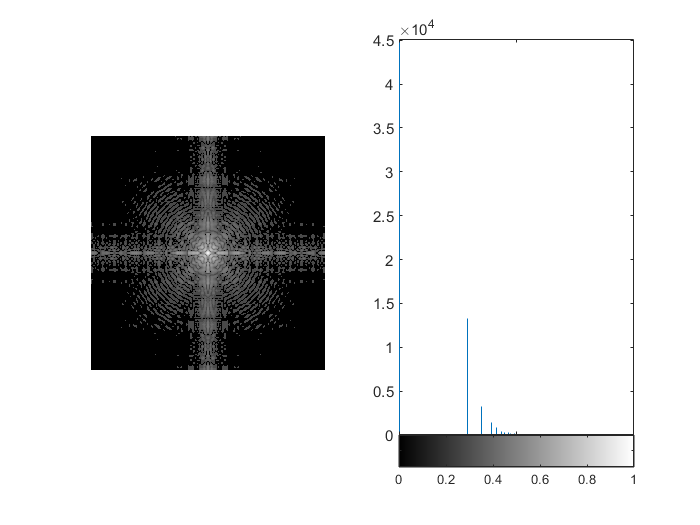

after_m = mat2gray(m_c * double(f) .^ m_e);
figure, subplot(1, 2, 1), imshow(after_m), subplot(1, 2, 2), imhist(after_m), axis tight

## 对比度拉伸

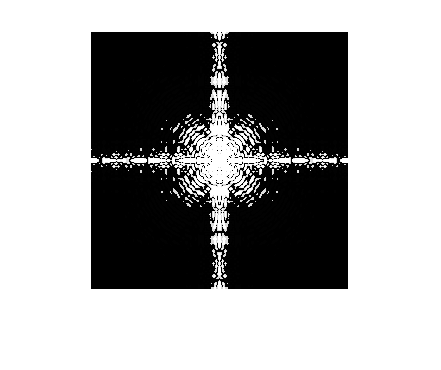

m = 5;
e = 10;
multi = im2uint8(mat2gray(1./(1 + (m./double(f) + eps).^e))); % 增加 eps 防止 0 值
figure
imshow(multi);

## 归一化直方图

h = imhist(f, 2) / numel(f) % b = 2, 分成两级灰度，所以如果是 8bit 图像，0~127 128 ~ 255 分成两种

h =     0.9997
    0.0003


## 绘制直方图

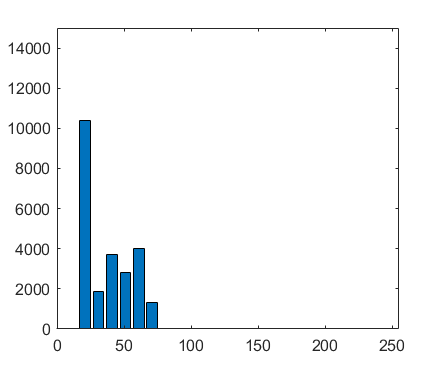

f = imread('./DIP-Ex/pic/dipum_images_ch03/Fig0308(a)(pollen).tif');
h = imhist(f);
h1 = h(1:10:256); % 间隔采样
horz = 1:10:256; % 水平轴增量
bar(horz, h1); % bar(horz, v, width) v 是被绘制的点
% 设置参考轴和刻度要在绘图函数之后
axis([0 255 0 15000]);
set(gca, 'xtick', 0:50:255);
set(gca, 'ytick', 0:2000:15000); % gca 获得当前轴，2000 为间隔

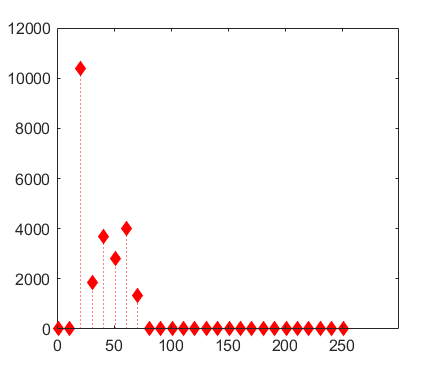

stem(horz, h1, 'r:d', 'filled'); % 'r:d' 是直方图中线和点的样式
set(gca, 'xtick', 0:50:255);
set(gca, 'ytick', 0:2000:15000); % gca 获得当前轴，2000 为间隔

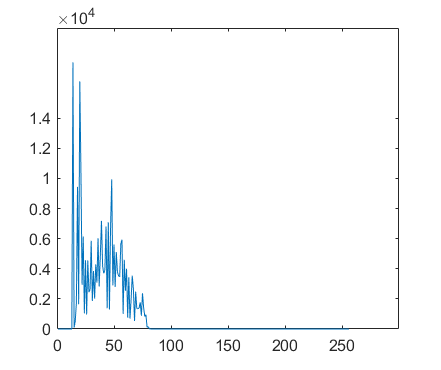

plot(h)
set(gca, 'xtick', 0:50:255);
set(gca, 'ytick', 0:2000:15000); % gca 获得当前轴，2000 为间隔

## 直方图均衡化

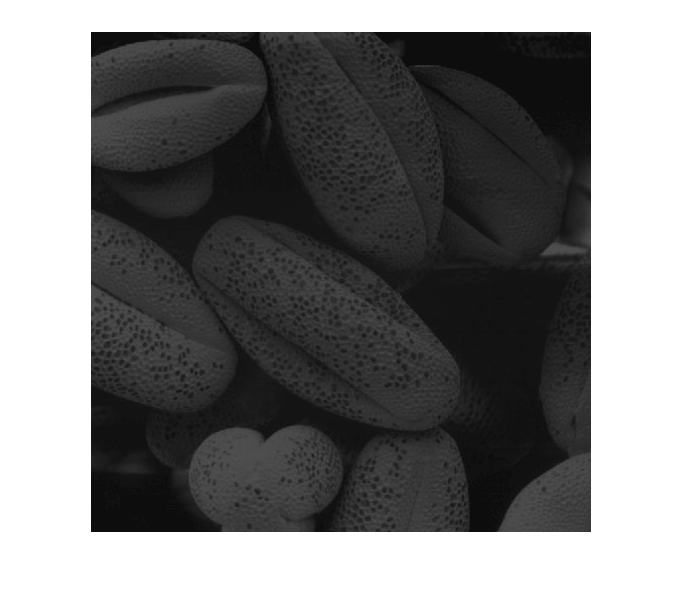

f = imread('./DIP-Ex/pic/dipum_images_ch03/Fig0308(a)(pollen).tif');
imshow(f);

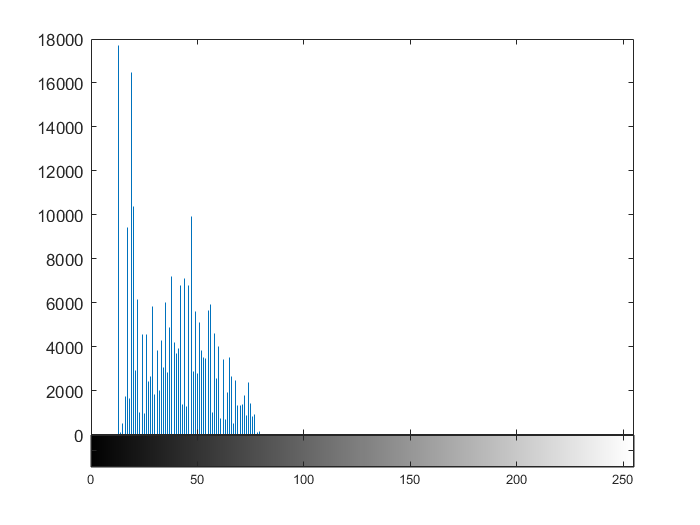

figure, imhist(f); % 很明显灰度局限在一个较暗的范围
ylim('auto')

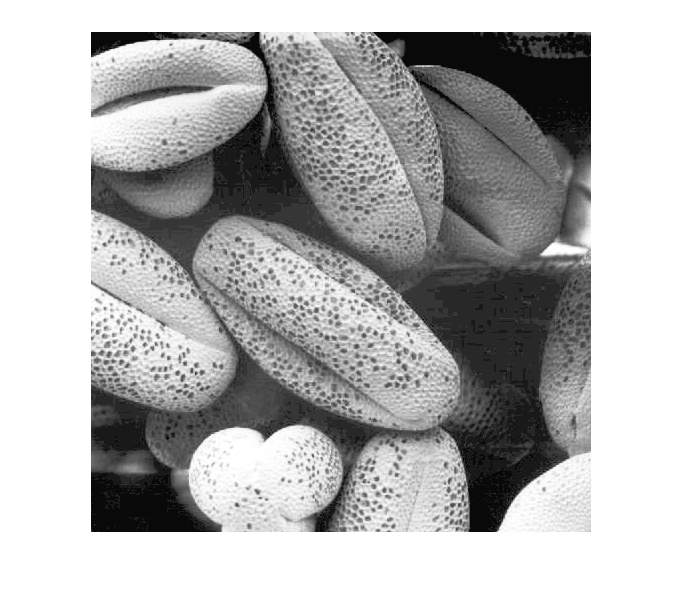

g = histeq(f, 256); % histeq 用于直方图均衡，原理是离散随机变量的分布律方式, 256 表明层级, 与图统一层级的话，直接执行均衡化函数
figure, imshow(g);

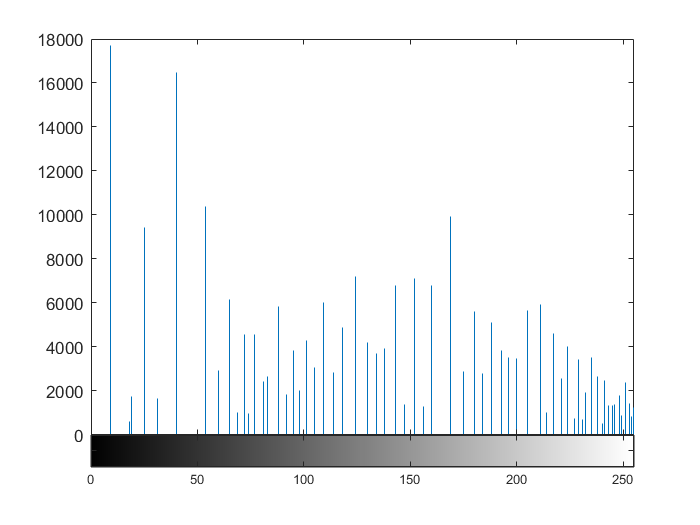

figure, imhist(g);
ylim('auto'); % 明显直方图范围大了，对比度增加

## 直方图匹配

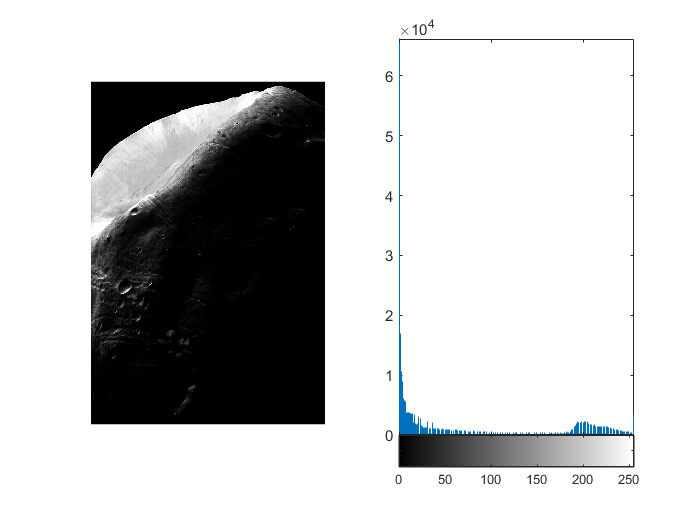

f = imread('./DIP-Ex/pic/dipum_images_ch03/Fig0310(a)(Moon Phobos).tif');
figure
subplot(1, 2, 1), imshow(f), subplot(1, 2, 2), imhist(f);

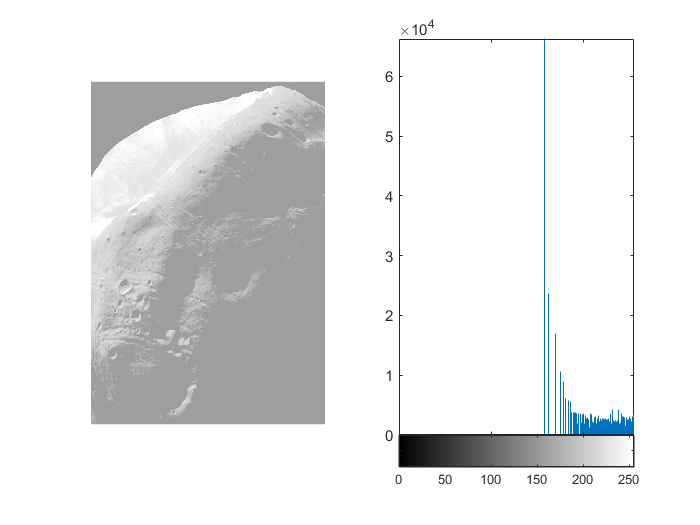

figure;
h = histeq(f, 256);
subplot(1, 2, 1), imshow(h), subplot(1, 2, 2), imhist(h); 

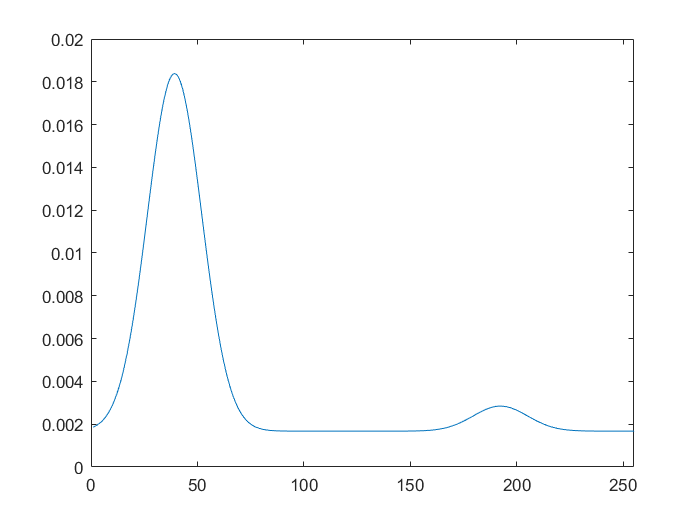

% 直方图均衡化，整体变灰了，还是集中在较亮一端造成褪色，原图像集中在 0 附近，导致累计函数特别陡峭(想一下离散的 分布函数
% 所以接下来用指定的一个直方图，然后用直方图匹配方法来均衡原图的直方图
% 注意保持原图特性，这里使用双峰高斯函数
m1 = 0.15;
sig1 = 0.05;
m2 = 0.75;
sig2 = 0.05;
a1 = 1;
a2 = 0.07;
k = 0.002;
c1 = a1 * (1 / ((2 * pi) ^ 0.5) * sig1);
k1 = 2 * (sig1 ^ 2);
c2 = a2 * (1 / ((2 * pi) ^ 0.5) * sig2);
k2 = 2 * (sig2 ^ 2);
z = linspace(0, 1, 256);
p = k + c1 * exp(-((z - m1) .^ 2) ./ k1) + c2 * exp(-((z - m2) .^ 2) ./ k2);
p = p ./ sum(p(:));
figure;
plot(p);
xlim([0 255]);

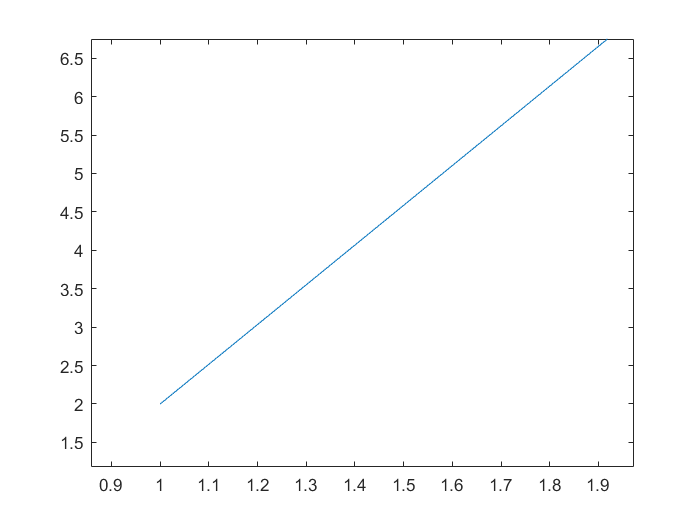

% y = kx + b 测试一下绘图
x = linspace(0, 256);
y = 2 * x + 2;
figure, plot(y), xlim([0 10]);

xlim([0.858 1.973])
ylim([1.18 6.75])

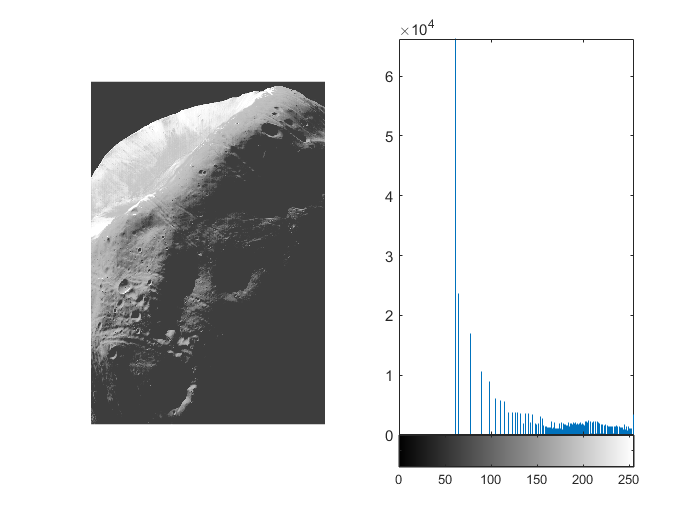

g = histeq(f, p); % 直方图匹配
figure;
subplot(1, 2, 1), imshow(g), subplot(1, 2, 2), imhist(g) % 和高数双峰比较，是类似，而且灰度被拓展到较为大的范围了，对比度增强。

## 空间滤波

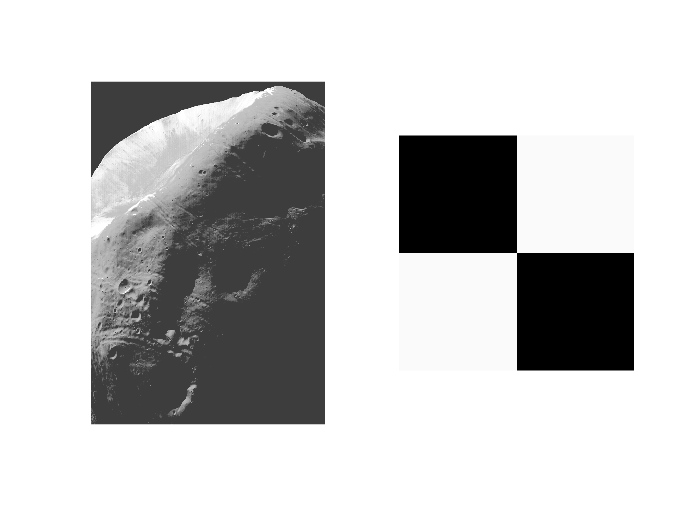

% 主要是中心点 + 对领域的处理
f = imread('./DIP-Ex/pic/dipum_images_ch03/Fig0315(a)(original_test_pattern).tif');
imshow(f);

%f = im2uint8(mat2gray(double(f)));
w = ones(31); % 近似一个平均滤波器，盒滤波
%w = w ./ 31^2 % 原因在下面写了
w, w ./ 32^2

w =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1 

ans = 	1.0e+-3 *

    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766
    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766
    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766    0.9766
    0.9766    0.9766    0.9766    0.9766    0.976

% 发现与书上 uint8 情况吻合，原因是 imfilter 与输入图像有相同类，输入图像是 uint8，输出自然也是
% 如果滤波后结果超过 0 255 范围，会自动截断。所以需要归一化系数，不然结果如下行结果所示
gd = imfilter(f, w), gd_ = imfilter(f, w ./ 31^2);

gd = 512×512 uint8 矩阵
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  

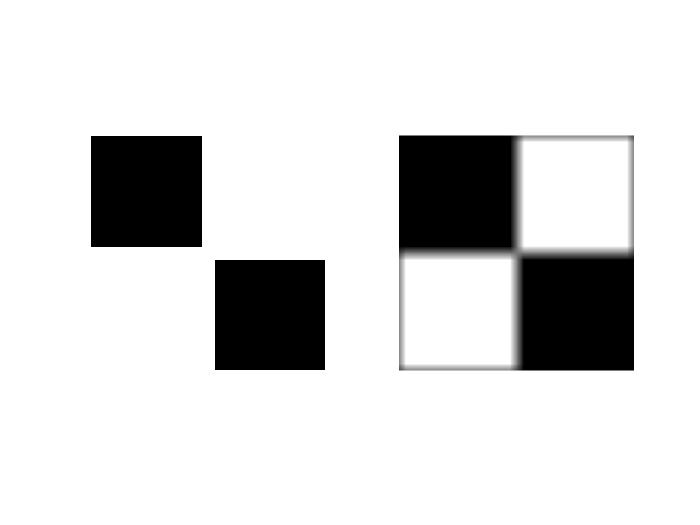

figure;
subplot(1, 2, 1), imshow(gd), subplot(1, 2, 2), imshow(gd_, [ ]); % 很明显边缘填充 0 会导致边缘模糊

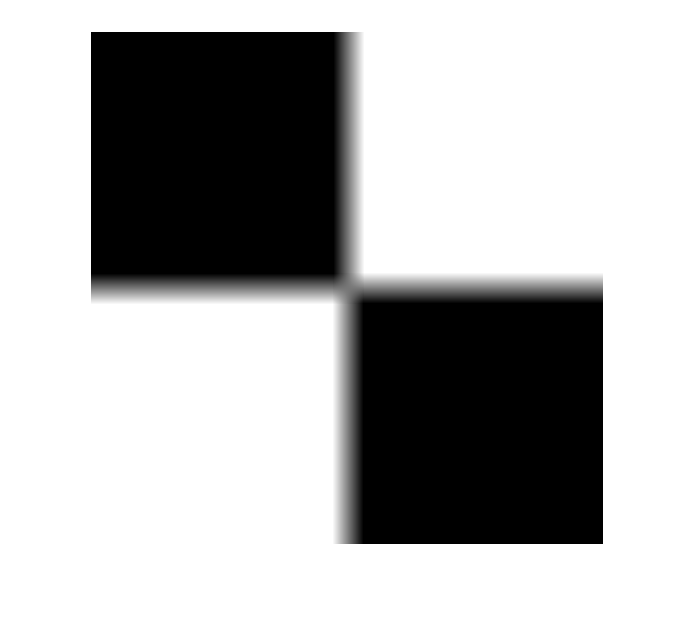

gr = imfilter(f, w ./ 31^2, 'replicate'); % 使用了 replicate 解决边缘模糊问题
figure, imshow(gr, [ ]);

## 非线性滤波

% 需要使用 colfilter，但 colflter 需要已经填冲过的图像，故先了解 padarray
f = [1, 2; 3, 4];
fp1 = padarray(f, [3, 2], 'replicate', 'post');
fp2 = padarray(f, [3, 2], 'replicate', 'both');
fp1

fp1 =      1     2     2     2
     3     4     4     4
     3     4     4     4
     3     4     4     4
     3     4     4     4


fp2 % 1 2 3 4 在中心，沿着上下左右第一个和最后一个开始填充，而且是复制。

fp2 =      1     1     1     2     2     2
     1     1     1     2     2     2
     1     1     1     2     2     2
     1     1     1     2     2     2
     3     3     3     4     4     4
     3     3     3     4     4     4
     3     3     3     4     4     4
     3     3     3     4     4     4


size(fp2, 1)

ans = 8

size(fp2, 2)

ans = 6

prod(fp2, 1) % 沿着第一维度乘积

ans =           81          81          81        4096        4096        4096


prod(fp2, 2)

ans =            8
           8
           8
           8
        1728
        1728
        1728
        1728


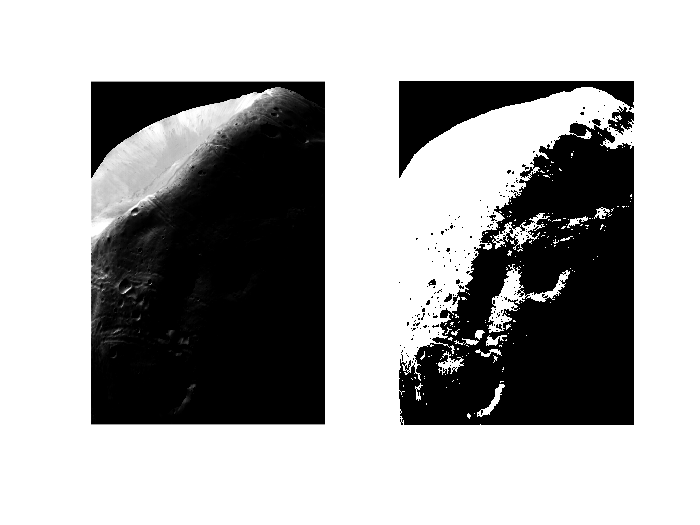

f = imread('./DIP-Ex/pic/dipum_images_ch03/Fig0310(a)(Moon Phobos).tif');
f1 = mat2gray(f);
f2 = f;
%f = [1, 2; 3, 4];
f1 = padarray(f1, [3 2], 'replicate'); 
f2 = padarray(f2, [3 2], 'replicate'); 
g1 = colfilt(f1, [3 2], 'sliding', @gmean);
g2 = colfilt(f2, [3 2], 'sliding', @gmean);
figure;
subplot(1, 2, 1), imshow(g1), subplot(1, 2, 2), imshow(g2);% 注意问题所在，就是没有将像素值映射到 0~1

## 利用 matlab 函数实现模板和滤波器

% 锐化滤波器 拉普拉斯
f = imread('./DIP-Ex/pic/dipum_images_ch03/Fig0316(a)(moon).tif')

f = 540×466 uint8 矩阵
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

w = (fspecial('laplacian', 0)); % 拉布拉斯算子 模板
double(w)

ans =      0     1     0
     1    -4     1
     0     1     0


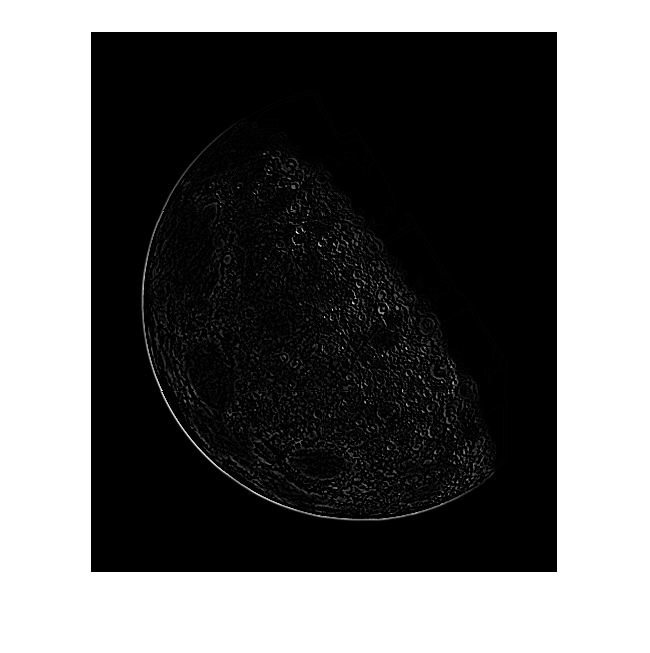

g1 = imfilter(f, w, 'replicate'); % 灰度值会被裁剪
figure, imshow(g1, [])

f2 = mat2gray(f); % double 不起作用
f2

f2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

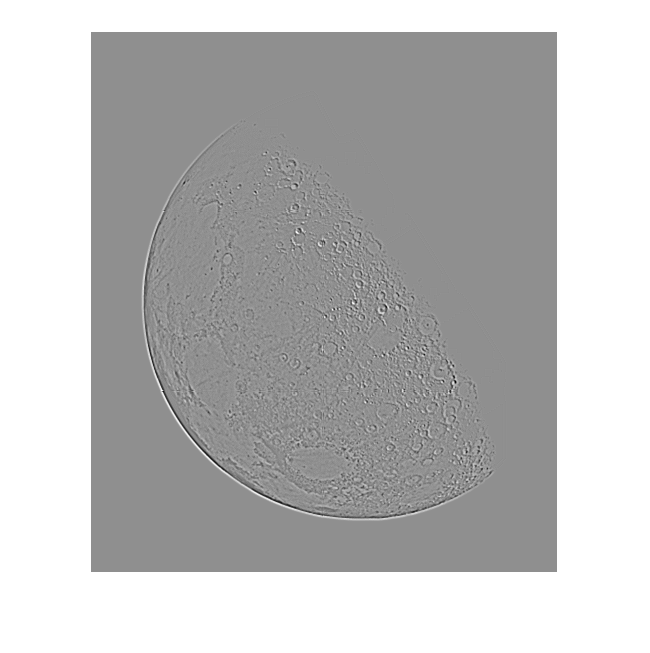

g2 = imfilter(f2, w, 'replicate'); % 滤波
figure, imshow(g2, []);

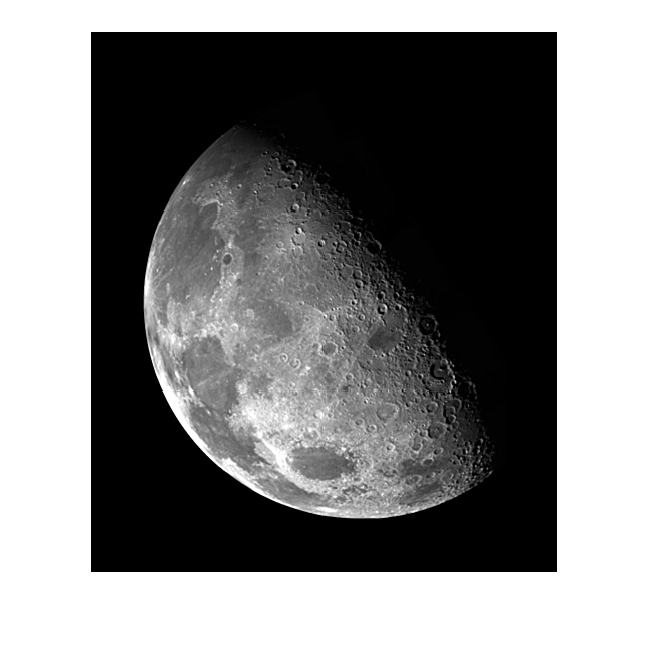

g = f2 - g2; % 拉普拉斯公式 f(x, y) + c * delta() 把没受影响的图像叠加上去，注意这里是减，因为模板中心是 -4 负数
figure, imshow(g) % imshow 默认图像是 [0 1] 之间的灰度，如果超过就截断为白色(255)

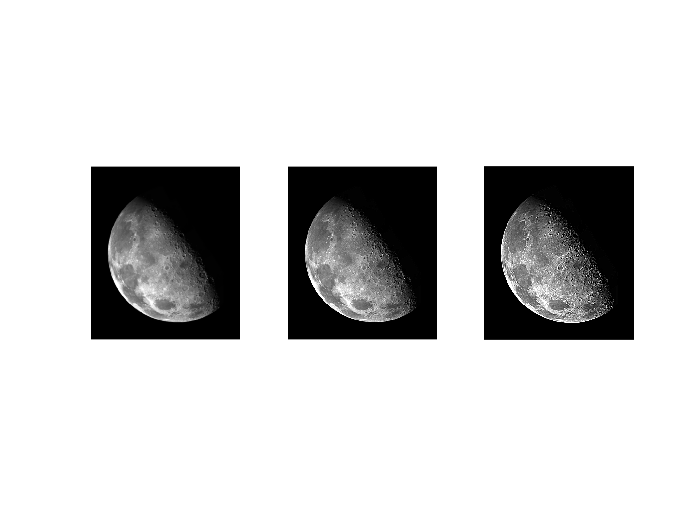

% 手工指定滤波器和增强技术的比较
f_d = mat2gray(f); % 注意点
w4 = fspecial('laplacian', 0);
w8 = [1 1 1; 1 -8 1; 1 1 1];
gw4 = imfilter(f_d, w4, 'replicate');
gw8 = imfilter(f_d, w8, 'replicate');
figure;
subplot(1, 3, 1), imshow(f_d), subplot(1, 3, 2), imshow(f_d - gw4), subplot(1, 3, 3), imshow(f_d - gw8); 

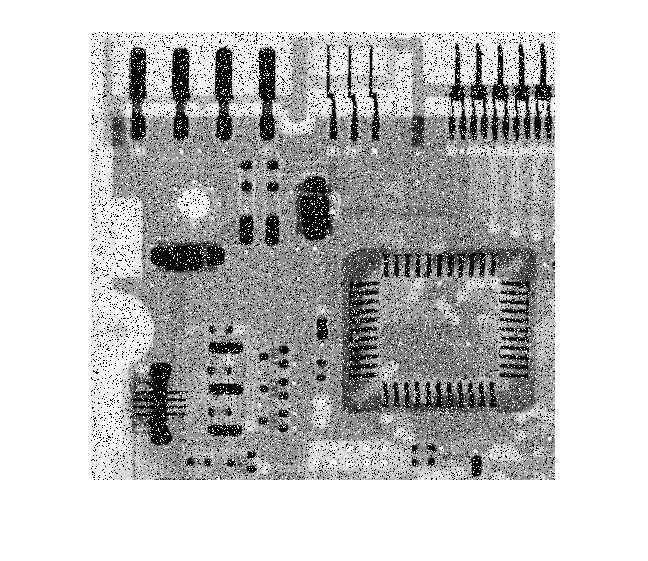

% 非线性空间滤波 统计排序
% ordfilt2(f, order, domain), order 邻域中第几个样本用于替代 domain 0 1 组成矩阵，1 表示这个位置像素要纳入计算，指定邻域
% 利用 medfilt2 中值滤波
f = imread('./DIP-Ex/pic/dipum_images_ch03/Fig0318(b)(ckt-board-slt-pep-both-0pt2).tif'); % 椒盐噪声
figure,imshow(f);

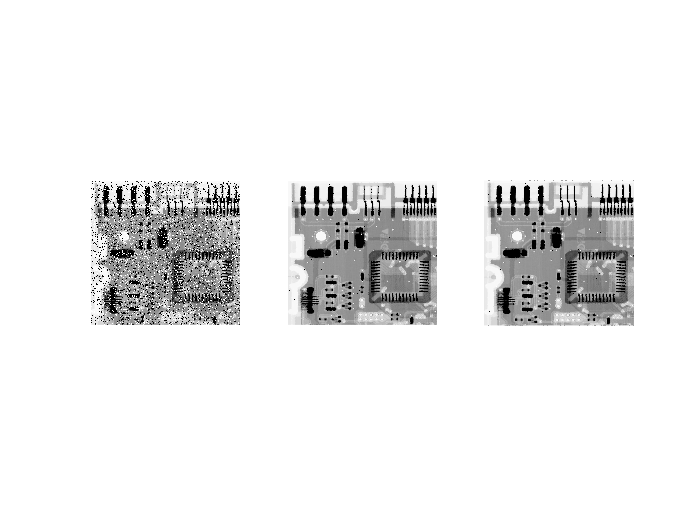

% 两个滤波器
g1 = ordfilt2(f, median(1:3*3), ones(3, 3)); % 自定义中值滤波 用中值代替中心像素
g2 = medfilt2(f); % 二维中值滤波
figure;
subplot(1, 3, 1), imshow(f), subplot(1, 3, 2), imshow(g1), subplot(1, 3, 3), imshow(g2);

function v = gmean(A)
    mn = size(A, 1); % colfilt 会把 A 拓展，他的行数就是 m * n https://blog.csdn.net/PanPan_1995/article/details/115390609
    v = prod(A, 1) .^ (1/mn);% 对第一维操作，得到一个行向量，内容是乘积
end

